# Robust control design for a quadcopter

### Define uncertain linear state-space model of quadcopter attitude using axis-angle representation

s = tf('s');

J_xx = ureal('J_xx', 0.001630, 'Percentage', 5);
J_yy = ureal('J_yy', 0.002156, 'Percentage', 5);
J_zz = ureal('J_zz', 0.003281, 'Percentage', 5);

A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     0 0 0 0 0 0;
     0 0 0 0 0 0;
     0 0 0 0 0 0];

B = [0 0 0;
     0 0 0;
     0 0 0;
     1/J_xx 0 0;
     0 1/J_yy 0;
     0 0 1/J_zz];

C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0];

D = [0 0 0;
     0 0 0;
     0 0 0];

Q = ss(A, B, C, D);
Q.StateName = {'theta_x', 'theta_y', 'theta_z', 'omega_x', 'omega_y', 'omega_z'};
Q.InputName = 'M_d';
Q.OutputName = 'bar_theta';


### Define uncertain transfer functions for actuator dynamics

F_tc = ureal('F_tc', 0.033, 'Percentage', 15);
F_k = ureal('F_k', 1, 'Percentage', 20);
F_td = 0.0349*1.26;

F_i = exp(-F_td*s)*F_k/(F_tc*s + 1)

Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 3 states.
The model uncertainty consists of the following blocks:
  F_k: Uncertain real, nominal = 1, variability = [-20,20]%, 1 occurrences
  F_tc: Uncertain real, nominal = 0.033, variability = [-15,15]%, 1 occurrences



F = [F_i  0       0; 
     0              F_i   0;
     0              0               F_i];
F.u = 'u';
F.y = 'M';


### Define uncertain transfer functions to act as uncertain unmodelled dynamics

DeltaQ = uss(ultidyn('DeltaQ', [3 3]));
DeltaQ(1,1) = DeltaQ(1,1)*0;%makeweight(0.25, 130, 10);
DeltaQ(2,2) = DeltaQ(2,2)*0;%makeweight(0.25, 130, 10);
DeltaQ(3,3) = DeltaQ(3,3)*0;%makeweight(0.25, 130, 10);
DeltaQ(1,2) = DeltaQ(1,2)*0;%1;
DeltaQ(1,3) = DeltaQ(1,3)*0;%1;
DeltaQ(2,1) = DeltaQ(2,1)*0;%1;
DeltaQ(2,3) = DeltaQ(2,3)*0;%1;
DeltaQ(3,1) = DeltaQ(3,1)*0;%1;
DeltaQ(3,2) = DeltaQ(3,2)*0;%1;
DeltaQ.InputName = 'M';
DeltaQ.OutputName = 'd_DeltaQ';

% bodemag(DeltaQ)


### Summing junction to add unmodelled dynamics and load distubances to the body moments

d_add = sumblk('M_d = d + M + d_DeltaQ', 3);


### Connect above blocks to create the plant model

P = connect(F, DeltaQ, d_add, Q, {'u', 'd'}, {'bar_theta'});

% bodemag(P(1:3,1:3)), title('Bode magnitude of plant input')
% bodemag(P(1:3,4:6))
% bodemag(P(2,2))
% bodemag(P(3,3))


## ADRC control design

w_c = 2*2*pi % rad/s 150

w_c = 12.5664

w_o = w_c*6 % rad/s

w_o = 75.3982

b_0 = 590 % roll and pitch 590

b_0 = 590

% b0 = 296 % yaw

ONE = ones(1,1,'like',b_0);
A_eso = [0,1;0,0]*ONE;
B_eso = [0;b_0]*ONE;
C_eso = [1;0]*ONE;
L_eso = [3*w_o;3*w_o^2;w_o^3]*ONE;

## PID control design

### Roll controller

Ts = 1;
OS = 15;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts

wn = 7.7380

wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = 85*pi/180;%88*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.2305

beta = w_max^2/alpha

beta = 120.9274


K = 0.00194; %0.0008
T_i = 100000; % 4

G_PIDx = (K*(1 + s/alpha)*(1 + T_i*s))/(s*T_i*(1 + s/beta))


G_PIDx =
 
  2.346e04 s^2 + 5408 s + 0.05408
  -------------------------------
     2.305e04 s^2 + 2.788e06 s
 
Continuous-time transfer function.


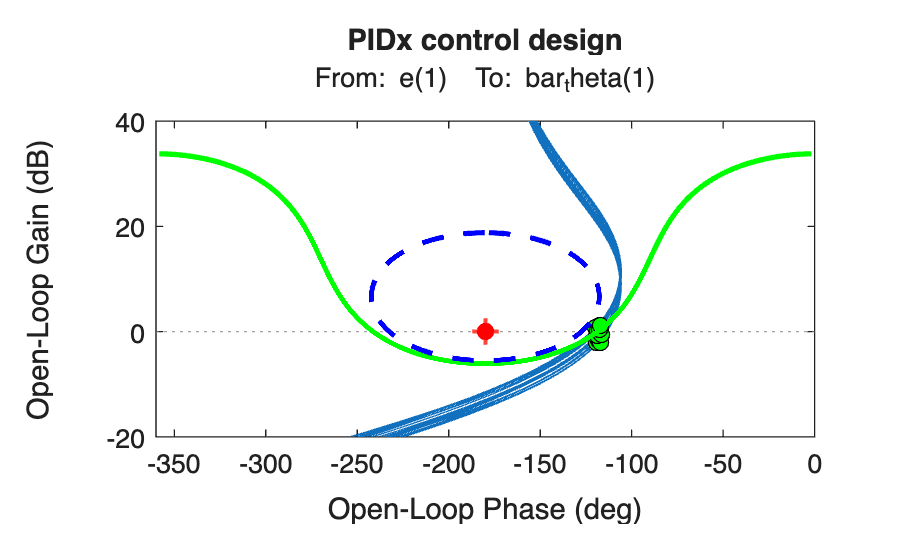

G_PIDx.InputName = {'e(1)'};
G_PIDx.OutputName = {'u(1)'};

% bodemag(G_PIDx)

L_PIDx = connect(G_PIDx, P(1,1), {'e(1)'}, {'bar_theta(1)'});

% bodemag(L_PIDx)

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PIDx);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PIDx,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PIDx control design')


hold off

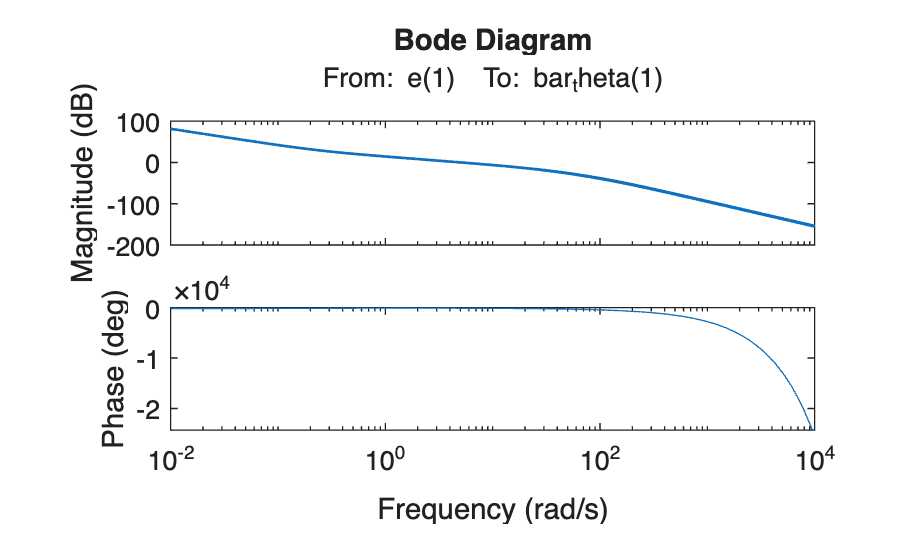


bode(L_PIDx)

opts = robOptions('Display', 'on', 'Sensitivity', 'on');
[margin, wcu, info] = robstab(feedback(L_PIDx, 1), opts)

Computing peak...  Percent completed: 100/100
System is robustly stable for the modeled uncertainty.
 -- It can tolerate up to 499% of the modeled uncertainty.
 -- There is a destabilizing perturbation amounting to 500% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 0.00154 rad/seconds.
 -- Sensitivity with respect to each uncertain element is:            
      100% for F_k. Increasing F_k by 25% decreases the margin by 25%.
      0% for F_tc. Increasing F_tc by 25% decreases the margin by 0%. 
      0% for J_xx. Increasing J_xx by 25% decreases the margin by 0%. 


margin = struct with fields:
           LowerBound: 4.9900
           UpperBound: 5.0000
    CriticalFrequency: 0.0015


wcu = struct with fields:
     F_k: 1.9864e-06
    F_tc: 0.0577
    J_xx: 0.0016


info = struct with fields:
                Model: 1
            Frequency: [2×1 double]
               Bounds: [2×2 double]
    WorstPerturbation: [2×1 struct]
          Sensitivity: [1×1 struct]


### Pitch Controller

Ts = 1;
OS = 15;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = 85*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 );
beta = w_max^2/alpha;

K = 0.00264;
T_i = 1000000; %4.5


G_PIDy = K*(1 + s/alpha)*(1 + T_i*s)/(s*T_i*(1 + s/beta))


G_PIDy =
 
  3.192e05 s^2 + 7.359e04 s + 0.07359
  -----------------------------------
       2.305e05 s^2 + 2.788e07 s
 
Continuous-time transfer function.


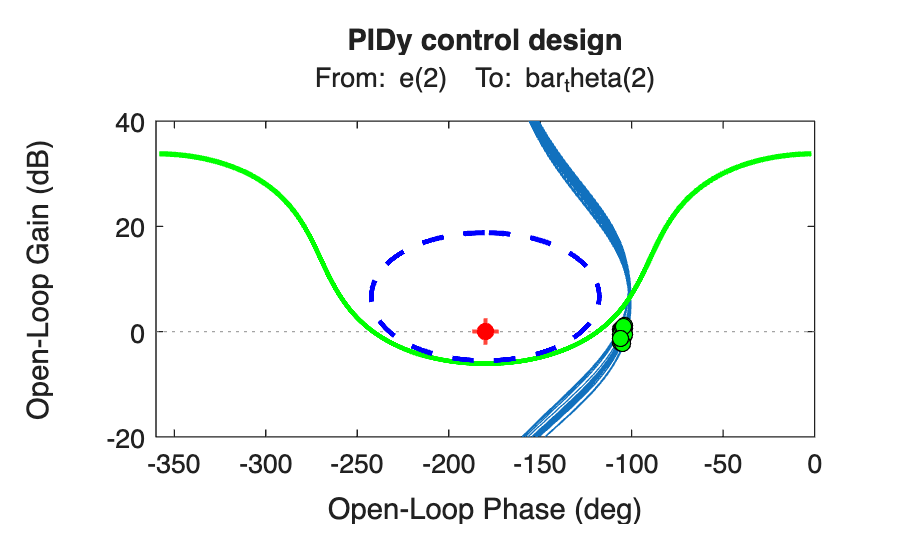

G_PIDy.InputName = {'e(2)'};
G_PIDy.OutputName = {'u(2)'};

L_PIDy = connect(G_PIDy, P(2,2), {'e(2)'}, {'bar_theta(2)'});

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PIDy);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PIDy,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PIDy control design')

hold off

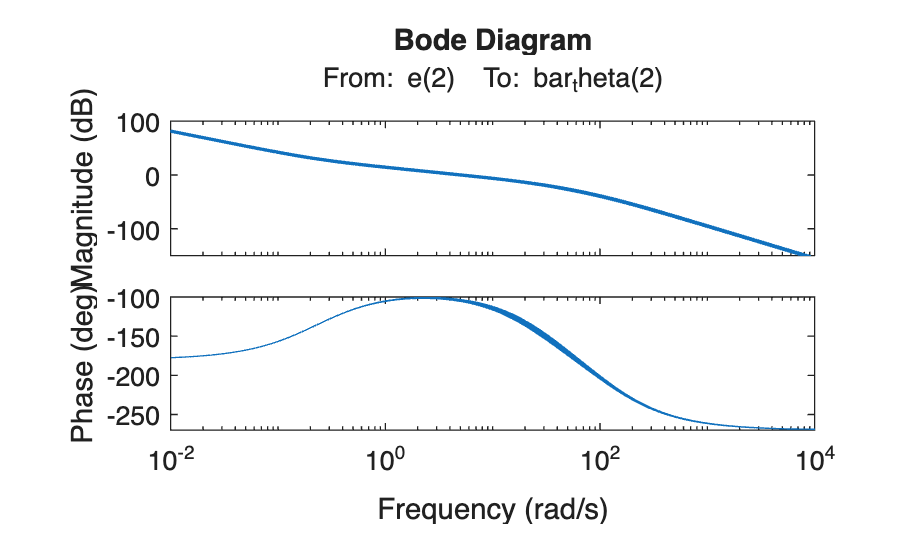


bode(L_PIDy)

### Yaw controller

Ts = 1.6;
OS = 15;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = 76*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 );
beta = w_max^2/alpha;

K = 0.0056;
T_i = 10000000; % 3


G_PIDz = K*(1 + s/alpha)*(1 + T_i*s)/(s*T_i*(1 + s/beta))


G_PIDz =
 
  1.505e06 s^2 + 6.098e05 s + 0.06098
  -----------------------------------
       4.052e06 s^2 + 1.089e08 s
 
Continuous-time transfer function.


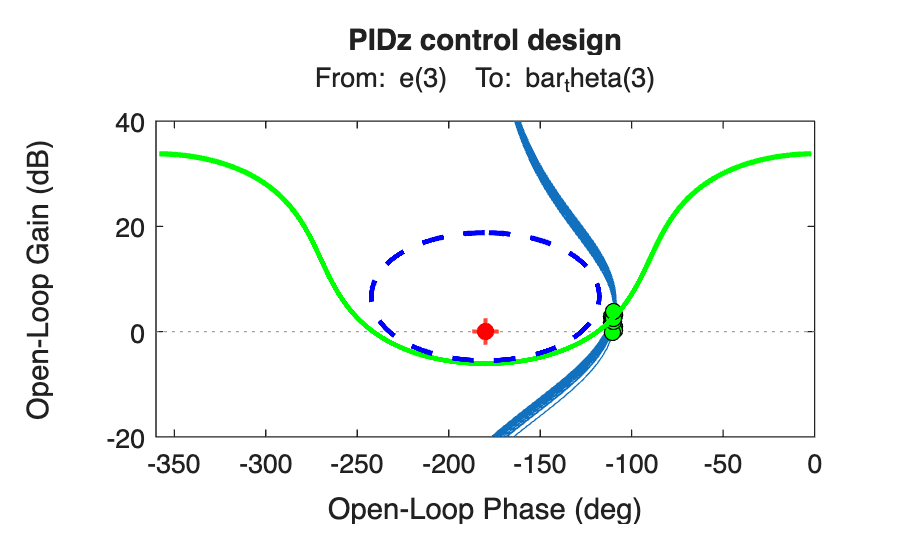

G_PIDz.InputName = {'e(3)'};
G_PIDz.OutputName = {'u(3)'};

L_PIDz = connect(G_PIDz, P(3,3), {'e(3)'}, {'bar_theta(3)'});

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PIDz);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PIDz,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PIDz control design')

hold off

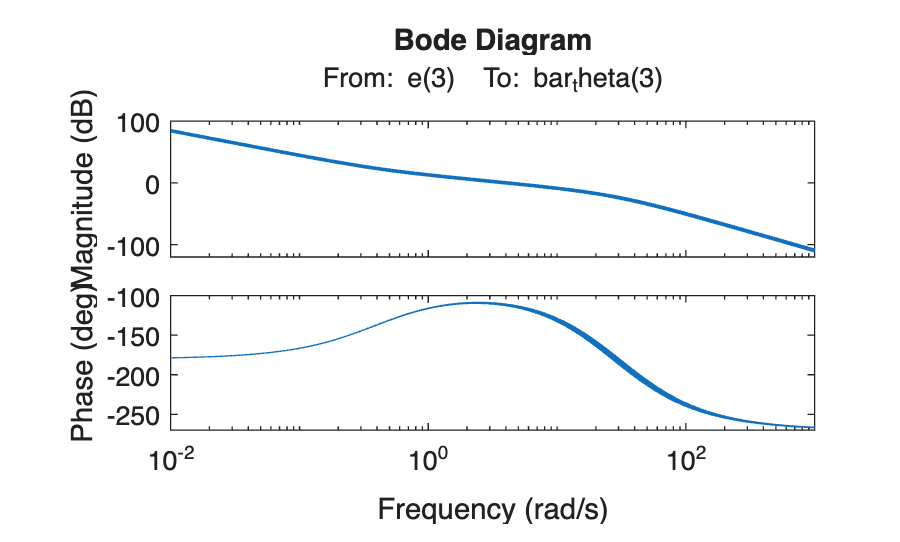


bode(L_PIDz)

## Set up weighting function and peripheral blocks used in h-infinity design

### Error signal (or Performance) weighting function

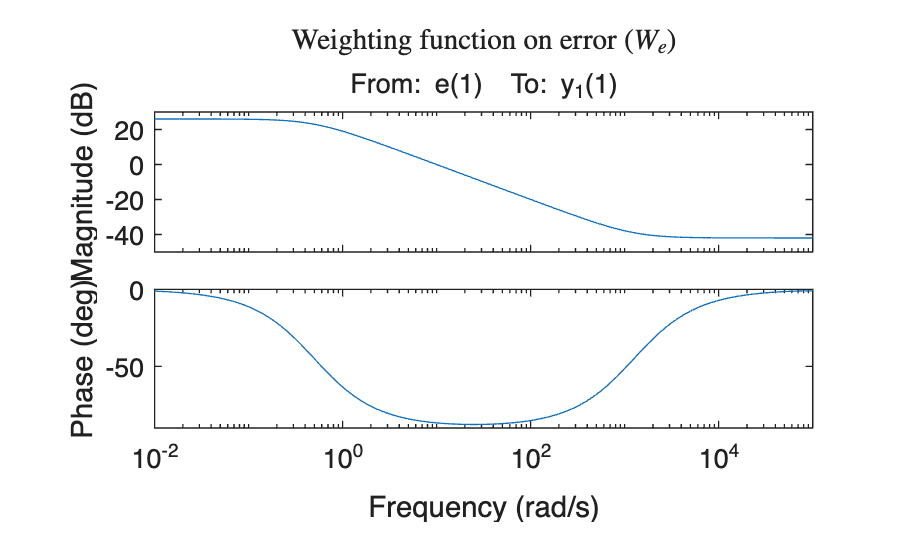

W_e = [(s/62.8 + 20)/(2*s+1) 0 0;
        0   (s/62.8 + 20)/(2*s+1) 0;
        0   0   (s/62.8 + 20)/(2*s+1)];

% W_e = [ ((s^2 +30.67*s + 247.3)/((s+1000)*(s+30.67)*(s+0.001)))   0       0;
%         0       ((s^2 +30.67*s + 247.3)/((s+1000)*(s+30.67)*(s+0.001)))   0;
%         0       0       ((s^2 +30.67*s + 247.3)/((s+1000)*(s+30.67)*(s+0.001)))];
W_e.u = 'e';
W_e.y = 'y_1';

bode(W_e(1,1)), title("Weighting function on error ($W_e$)", 'Interpreter','latex')

### Control signal (or Control effort) weighting function

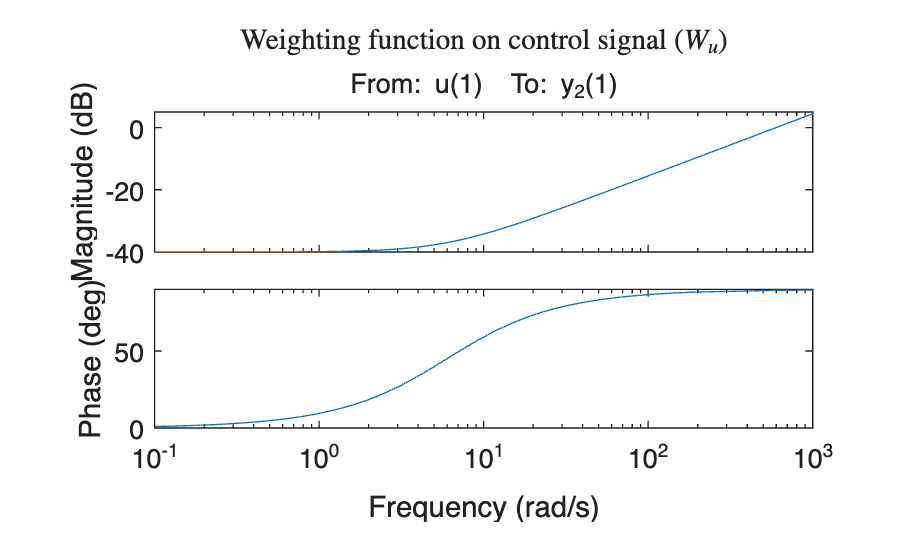

M_u = 100; % peak gain of the (controller gain * output sensitivity)
omega_bc = 600; % rad/s - controller bandwidth OR desired noise cutoff frequency
epsilon_u = 0.001;

W_u = [ ((s + omega_bc/M_u)/(epsilon_u*s + omega_bc))   0       0;
        0       ((s + omega_bc/M_u)/(epsilon_u*s + omega_bc))   0;
        0       0       ((s + omega_bc/M_u)/(epsilon_u*s + omega_bc))];
W_u.u = 'u';
W_u.y = 'y_2';

bode(W_u(1,1)), title("Weighting function on control signal ($W_u$)", 'Interpreter','latex')

### Output (or Uncertainty/robustness) weighting function

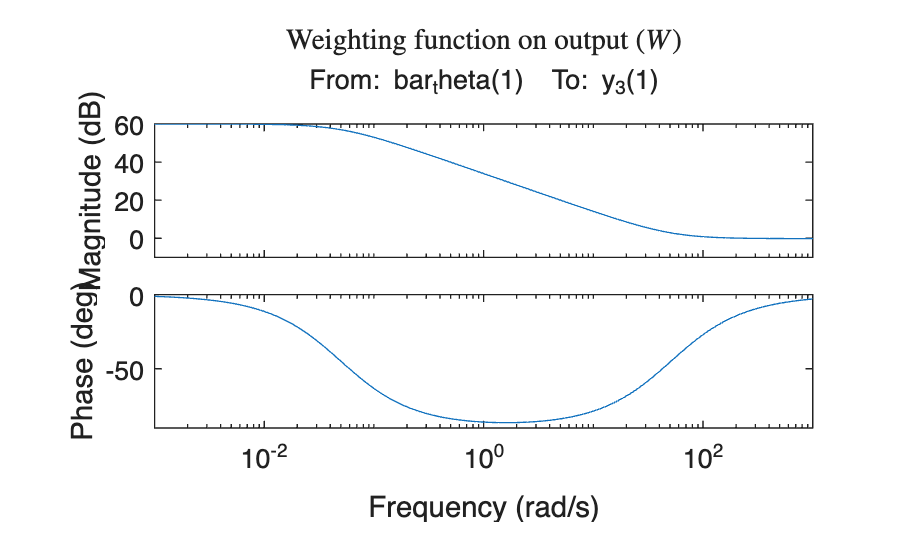

M_s = 1.02; % peak gain of output sensitivity (sensitivity of y to d)
omega_b = 50; % rad/s
epsilon = 0.001;

W = [ ((s/M_s + omega_b)/(s + omega_b*epsilon))   0       0;
        0       ((s/M_s + omega_b)/(s + omega_b*epsilon))   0;
        0       0       ((s/M_s + omega_b)/(s + omega_b*epsilon))];
W.u = 'bar_theta';
W.y = 'y_3';

bode(W(1,1)), title("Weighting function on output ($W$)", 'Interpreter','latex')

### Input/reference signal shaping transfer function

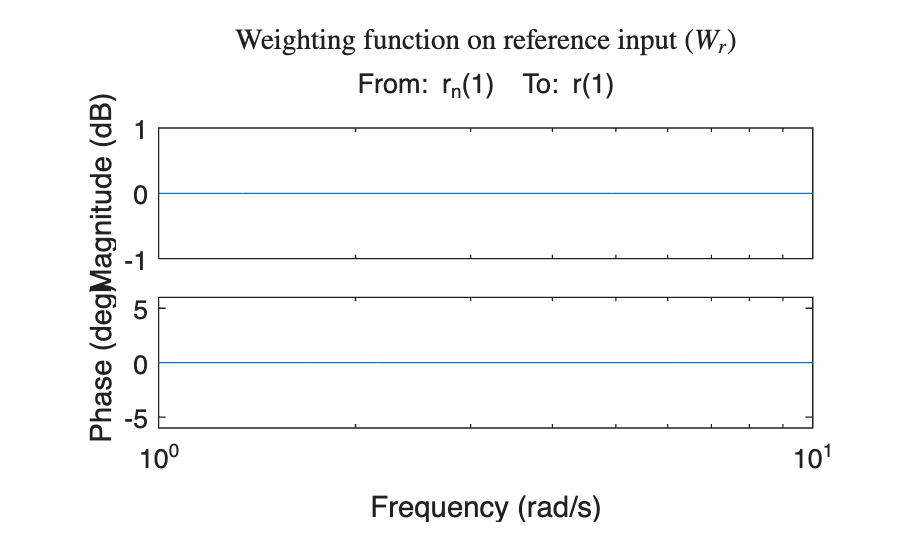

W_r = [ tf(1)   0       0;
        0       tf(1)   0;
        0       0       tf(1)];
W_r.u = 'r_n';
W_r.y = 'r';

bode(W_r(1,1)), title("Weighting function on reference input ($W_r$)", 'Interpreter','latex')

### Load disturbance shaping transfer function

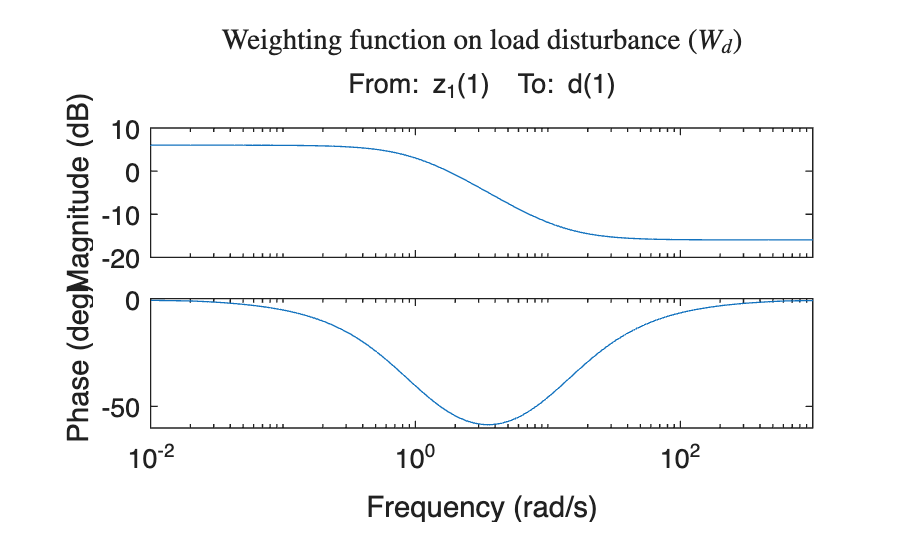

M_d = 2;
omega_d = 1*2*pi(); % rad/s

W_d = [ (s/omega_d + M_d)/(s + 1)   0       0;
        0       (s/omega_d + M_d)/(s + 1)   0;
        0       0       (s/omega_d + M_d)/(s + 1)];
W_d.u = 'z_1';
W_d.y = 'd';

bode(W_d(1,1)), title("Weighting function on load disturbance ($W_d$)", 'Interpreter','latex')

### Noise shaping transfer function

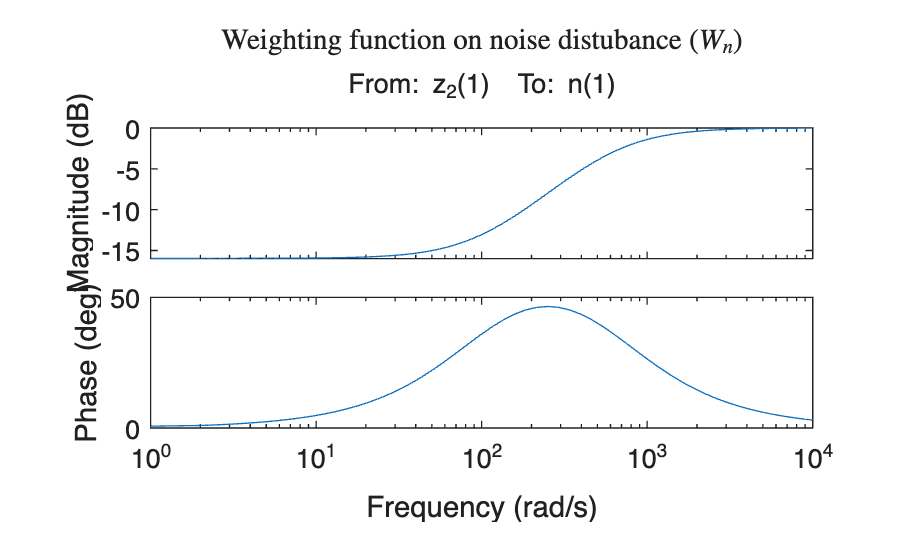

W_n = [ (s + 100)/(s + 628)   0       0;
        0       (s + 100)/(s + 628)   0;
        0       0       (s + 100)/(s + 628)];
W_n.u = 'z_2';
W_n.y = 'n';

bode(W_n(1,1)), title("Weighting function on noise distubance ($W_n$)", 'Interpreter','latex')

### Summing junctions for reference/error and noise injection

ref_diff = sumblk('e = r - bar_theta_n', 3);
n_add = sumblk('bar_theta_n = bar_theta + n', 3);


Hinfsyn_sys_inputs = {'r_n', 'z_1', 'z_2', 'u'};
Hinfsyn_sys_outputs = {'y_1', 'y_2', 'y_3', 'e'};

Hinfsyn_sys = connect(F, W_d, DeltaQ, d_add, Q, W, W_n, n_add, W_r, ref_diff, W_e, W_u, Hinfsyn_sys_inputs, Hinfsyn_sys_outputs);
Hinfsyn_sys.NominalValue


ans =
 
  A = 
                  ?        ?        ?        ?        ?        ?        ?        ?        ?        ?        ?        ?  theta_x  theta_y  theta_z  omega_x  omega_y  omega_z        ?        ?        ?        ?        ?        ?        ?        ?        ?        ?        ?        ?
   ?              1        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0
   ?              0        1       -1        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0
   ?          0.033        0        1        0        0        0        0        0        0        0        0        0        0        0     


n_out = 3; % number of controller outputs
n_in = 3; % number of controller inputs

G_hinf = ss(zeros(n_out, n_in));

opts = hinfsynOptions('Display', 'on', 'Regularize', 'off');

[G_hinf(:,:), ~, gamma, info] = hinfsyn(Hinfsyn_sys,n_in,n_out, opts);

Error using DynamicSystem/hinfsyn (line 121)
The "hinfsyn" command cannot be used for continuous-time models with delays. Use the "pade" command to approximate delays.

info

G_hinf = tf(ss(round(G_hinf.A, 4), round(G_hinf.B, 4), round(G_hinf.C, 4), round(G_hinf.D, 4)));
G_hinf.u = {'e'}; G_hinf.y = {'u'}

L_hinf = connect(G_hinf, P, {'e', 'd'}, 'bar_theta');


bode(L_hinf(1,1), L_PIDx), legend("H-inf x", "PIDx")
nichols(L_hinf(1,1), L_PIDx), legend("H-inf x", "PIDx")

CL_hinf = connect(G_hinf, F, DeltaQ, d_add, Q, n_add, ref_diff, {'r' 'd', 'n'}, {'e', 'u','bar_theta'});
% CL_hinf.NominalValue
bodemag(tf(CL_hinf(1,1)), 1/W_e(1,1))
bodemag(tf(CL_hinf(4,1)), 1/W_u(1,1))
bodemag(tf(CL_hinf(7,1)), 1/W(1,1))

opts = robOptions('Display', 'on', 'Sensitivity', 'on');
[margin, wcu, info] = robstab(CL_hinf, opts)


n_out = 3; % number of controller outputs
n_in = 3; % number of controller inputs

G_mu = ss(zeros(n_out, n_in));

opts = musynOptions('Display', 'short');

% [G_mu(:,:), perf, info] = musyn(Hinfsyn_sys,n_in,n_out, opts)
info

G_mu = tf(ss(round(G_mu.A, 4), round(G_mu.B, 4), round(G_mu.C, 4), round(G_mu.D, 4)));
G_mu.u = {'e'}; G_mu.y = {'u'};

L_mu = connect(G_mu, P, 'e', 'bar_theta');

bode(L_mu(1,1), L_PIDx), legend("mu syn x", "PIDx")
nichols(L_mu(1,1), L_PIDx), legend("mu syn x", "PIDx")


opts = robOptions('Display', 'on', 'Sensitivity', 'on');
[margin, wcu, info] = robstab(connect(G_mu, F, DeltaQ, d_add, Q, n_add, ref_diff, {'r', 'd', 'n'}, 'bar_theta'), opts)
